# **Understanding and Improving Network Accuracy**

In this demonstration, you will learn about network accuracy and certain methods of improving it. The workshop will cover the following topics in detail:

- Relationship between amount of data and network accuracy

- Class imbalance and how to work around this issue

- Overfitting and data transformation

There are other techniques that are not directly addressed, which will be mentioned at the end. These include Bayesian optimization of hyperparameters, choosing different solvers, and generation of synthetic data.

## Set Configuration Options

addpath(genpath(pwd));
w = warning('off');
clear


# Relationship between Data and Network Accuracy

In this first part, we will examine how the amount of training data affects the accuracy of our network. We will be working with the food101 dataset from the transfer learning example. You may recall the five categories - chocolate cake, french fries, hot-dog, ice cream, and pizza .

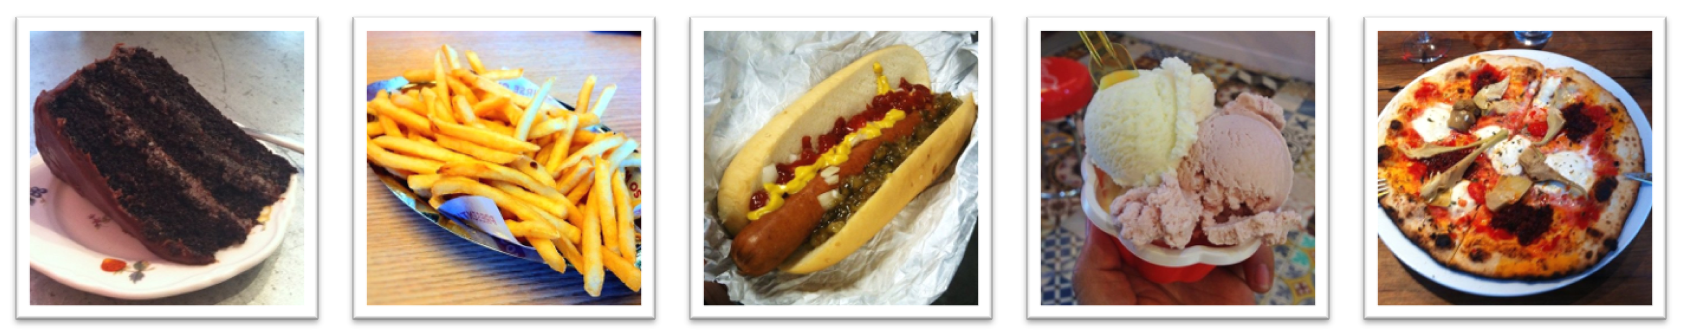

## Create Training, Validation and Test Datastores

 We will train our network to classify five categories of food with 8 training sets:

- 10 training examples per category (DS.train010)

- 25 training examples per category (DS.train025)

- 50 training examples per category (DS.train050)

- 100 training examples per category (DS.train100)

- 200 training examples per category (DS.train200)

- 400 training examples per category (DS.train400)

- 600 training examples per category (DS.train600)

- 800 training examples per cateogry (DS.train800)

`createTrainingDatastore` is a custom function that generates a datastore for each category and saves them in a struct called DS. You can access elements in a struct using dot notation (see syntax above

rootDataDir = [filesep 'MATLAB Drive', filesep, 'Workshop', filesep, 'LargeFiles'];

DS = createTrainingDatastore(rootDataDir);

We also have a validation and test dataset, each with 100 unique images. We'll keep these separate from the training data struct (DS).

valDir = [rootDataDir, filesep, '07-Data', filesep, 'ValData'];
valDS = imageDatastore(valDir,...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

testDir = [rootDataDir filesep, '07-Data', filesep, 'TestData'];
testDS = imageDatastore(testDir,...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

## Load Network

This is a series network with 22 layers and has an input requirement of 227 x 227 x 3.

load networkLayers.mat
% analyzeNetwork(newLayers)

## Create Augmented Image Datastore for Resizing

The most efficient way to resize images is to use `augmentedImageDatastore`. This is the fastest method of preprocessing training data because it automatically process data in mini batches. Another option is to use ReadFcn, which is a method in `imageDatastore`; however, this resizes images one-by-one.

inputSize = [227 227];

auDS.train010 = augmentedImageDatastore(inputSize,DS.train010);
auDS.train025 = augmentedImageDatastore(inputSize,DS.train025);
auDS.train050 = augmentedImageDatastore(inputSize,DS.train050);
auDS.train100 = augmentedImageDatastore(inputSize,DS.train100);
auDS.train200 = augmentedImageDatastore(inputSize,DS.train200);
auDS.train400 = augmentedImageDatastore(inputSize,DS.train400);
auDS.train600 = augmentedImageDatastore(inputSize,DS.train600);
auDS.train800 = augmentedImageDatastore(inputSize,DS.train800);

auTestDS = augmentedImageDatastore(inputSize,testDS);
auValDS = augmentedImageDatastore(inputSize,valDS);

## Set Training Hyperparameters

initiallearnrate = 0.001;
valDataPatience = 6;

trainOpts = trainingOptions('sgdm',...
    'InitialLearnRate',initiallearnrate,...
    'ValidationData',auValDS,...
    'Plots','training-progress',...
    'MiniBatchSize', 64,...
    'ValidationPatience', valDataPatience,...
    'Shuffle','every-epoch');

## Train Each Network

Without a powerful GPU, training 8 networks can take a significant amount of time. We recommend toggling the doTrain option to false.

Before running this section, take some time to think about what you think the accuracies will look like for each network. Questions to consider:

- How low will the accuracy of net010 be?

- How high will the accuracy of net800 be?

- What will be the disparity between the highest and lowest accuracy?

- Should we expect a linear relationship between accuracy and training data?

- What other factors affect network accuracy? (hint: we already talked about some of these!)

doTrain =    false;

if doTrain
    net010 = trainNetwork(auDS.train010, newLayers, trainOpts);
    net025 = trainNetwork(auDS.train025, newLayers, trainOpts);
    net050 = trainNetwork(auDS.train050, newLayers, trainOpts);
    net100 = trainNetwork(auDS.train100, newLayers, trainOpts);
    net200 = trainNetwork(auDS.train200, newLayers, trainOpts);
    net400 = trainNetwork(auDS.train400, newLayers, trainOpts);
    net600 = trainNetwork(auDS.train600, newLayers, trainOpts);
    net800 = trainNetwork(auDS.train800, newLayers, trainOpts);
else
    load('trainedNetworks.mat')
end


## View Training Plots

net800


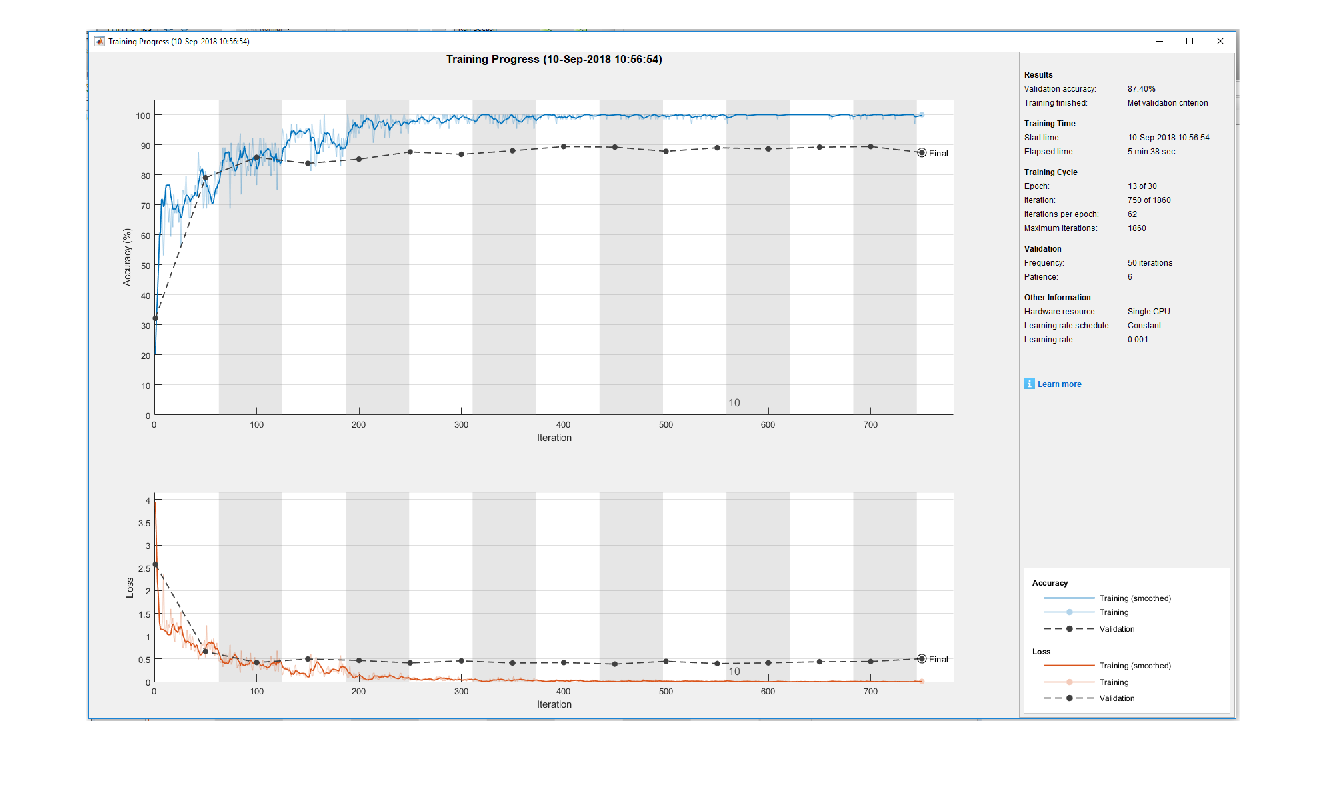

selectNetwork = 'net800';

viewTrainingPlots(selectNetwork)

**Discussion**:

Why do networks like net010 train so quickly, while networks like net800 have more complexity?

- *This occurs because of the amount of data passing through the network for training.*

- *Data is passed through in minibatches for training. For net010, we have a total of 50 training images, which means all of the data gets passed through in each epoch. The default max epoch is 30, so the entire network is trained within 30 iterations. Comparitively, net800 has 40,000 training images. This means it will take many iterations to pass all of the images through the network once - this would be one epoch. We have to train until the validation patience (6) is met, and this will take many epochs. *

Why is the training accuracy is near 100 percent, but the validation accuracy is lower?

- *This disparity is caused by a phenomenon called overfitting. This means that the network is really good at classifying things similar to the training set, but is not as good as generalizing to real world examples. When training a network, it is important to have training data that is similar to your test data otherwise overfitting will lead to a decrease in test accuracy. There are measures we can take to reduce this, which we will discuss in the last section.*

## Test Accuracy of Each Network

doTest  =    true;

if doTest
    [labels.train010, scores.train010] = classify(net010, auTestDS);
    [labels.train025, scores.train025] = classify(net025, auTestDS);
    [labels.train050, scores.train050] = classify(net050, auTestDS);
    [labels.train100, scores.train100] = classify(net100, auTestDS);
    [labels.train200, scores.train200] = classify(net200, auTestDS);
    [labels.train400, scores.train400] = classify(net400, auTestDS);
    [labels.train600, scores.train400] = classify(net600, auTestDS);
    [labels.train800, scores.train800] = classify(net800, auTestDS);
    
    accuracy.net010 = sum(labels.train010 == testDS.Labels)/numel(labels.train010);
    accuracy.net025 = sum(labels.train025 == testDS.Labels)/numel(labels.train025);
    accuracy.net050 = sum(labels.train050 == testDS.Labels)/numel(labels.train050);
    accuracy.net100 = sum(labels.train100 == testDS.Labels)/numel(labels.train100);
    accuracy.net200 = sum(labels.train200 == testDS.Labels)/numel(labels.train200);
    accuracy.net400 = sum(labels.train400 == testDS.Labels)/numel(labels.train400);
    accuracy.net600 = sum(labels.train600 == testDS.Labels)/numel(labels.train600);
    accuracy.net800 = sum(labels.train800 == testDS.Labels)/numel(labels.train800);
else
    load('trainedNetworkResults.mat')
end

**Questions to consider:**

- How will the amount of data affect network accuracy?

- What will the relationship look like? (i.e. linear, exponential, logarithmic etc.)

- What will be the disparity between the lowest amount of training data (10) vs. the highest (800)?

## Plot Network Accuracies

What conclusions can you draw from the test results?

T = 8×2 table
    Network     Accuracy
    ________    ________

    "net010"      58.2  
    "net025"      63.4  
    "net050"        72  
    "net100"      79.2  
    "net200"      83.8  
    "net400"      84.2  
    "net600"        85  
    "net800"      84.6  


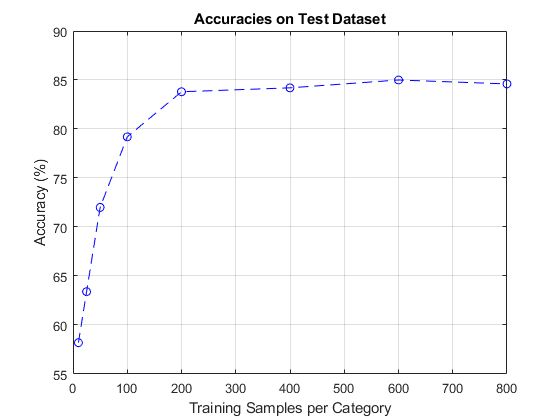

plotNetworkAccuracies(accuracy) %Make clear that graph is test accuracy

**Observations:**

- Logrithmic increase in accuracy while adding more data.

- Diminishing returns after about 200 training examples per category

## Key Takeaways:

- The relationship between amount of training examples and network accuracy is asymptotic increasing

- Sometimes the amount of data is the issue, but other times, we have to explore other avenues for increasing accuracy (hyperparameter tuning, augmentation, network architecture, etc.)

- Overfitting is characterized by a high training accuracy and a lower validation accuracy (more discussion in the last section).

# Managing Different Amounts of Data per Category

When working with data in the real world, we might find ourselves with more data in one category than another. In this section, we will explore what happens to our results in this scenario and how to mitigate the issue that may arise.

## Create Datastore

We will start by creating an image datastore with our unbalanced dataset. This dataset contains the following image counts:

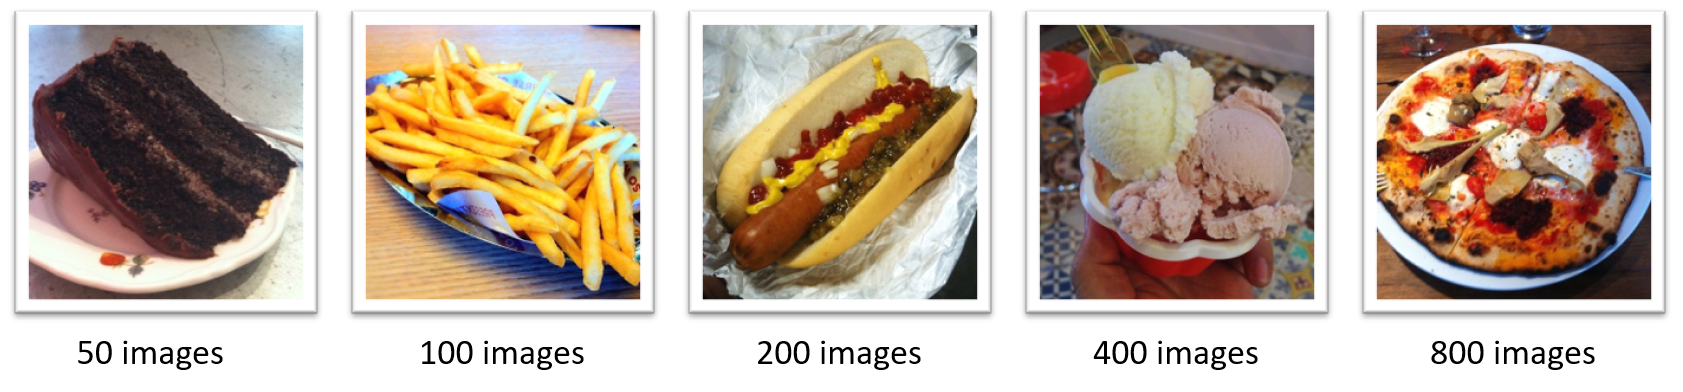

- Chocolate cake = 50 training examples

- French fries = 100 training examples

- Hot dog = 200 training examples

- Ice cream = 400 training examples

- Pizza = 800 training examples

imdsPath = [rootDataDir, filesep, '07-Data', filesep, 'UnbalancedDataset'];
imds = imageDatastore(imdsPath,...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');
auimds = augmentedImageDatastore(inputSize,imds);

## Set Training Options

initiallearnrate = 0.001;
valDataPatience = 6;

trainOpts = trainingOptions('sgdm',...
    'InitialLearnRate',initiallearnrate,...
    'ValidationData',auValDS,...
    'Plots','training-progress',...
    'MiniBatchSize', 64,...
    'ValidationPatience', valDataPatience);

## Train Network

**Questions to consider before seeing results:**

- What do you think will be the overall accuracy of the network? Why?

-  Do you think the network will have an even or uneven classiication of the different categories?

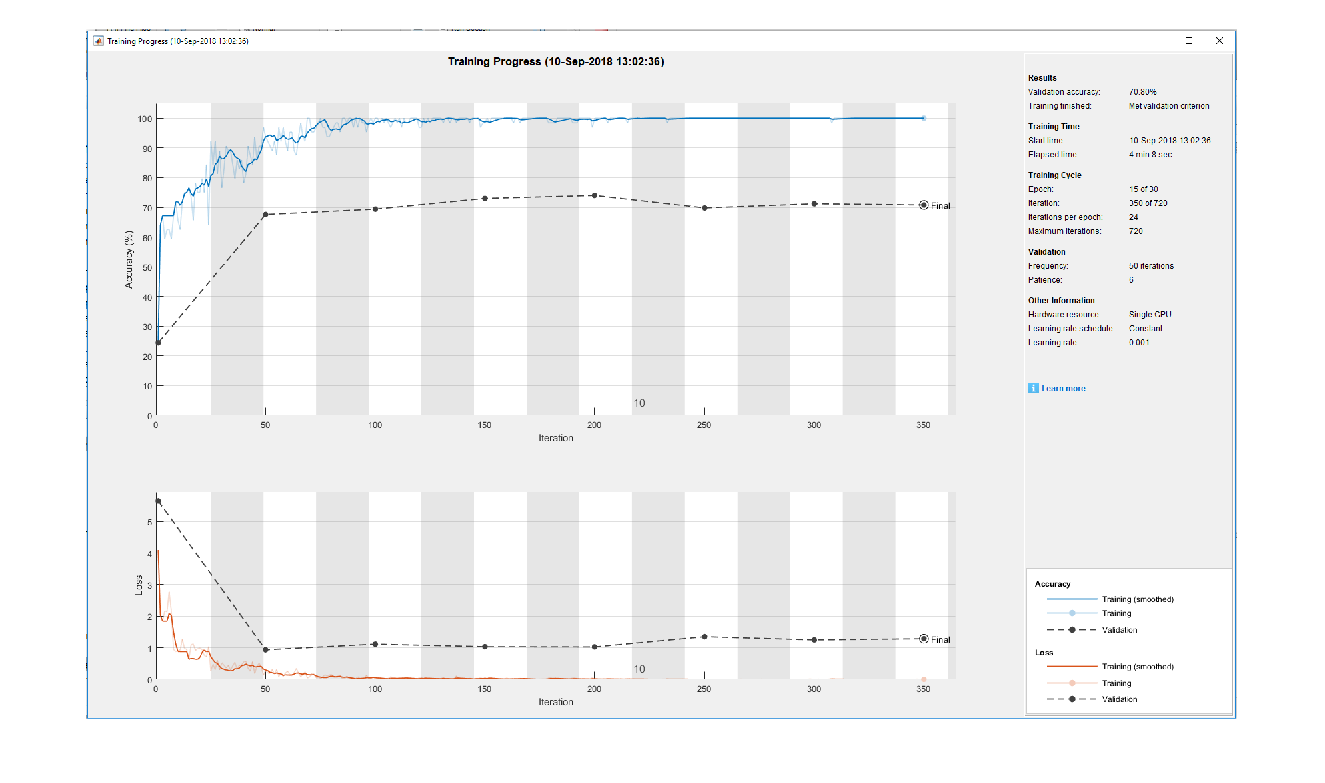

if doTrain
    netUnbalanced = trainNetwork(auimds, newLayers, trainOpts);
else
    load('netUnbalanced.mat');
    imshow(imread('netUnbalanced.PNG'));

end

## Test Network

if doTest
    [labelsUnbalanced scoreUnbalanaced] = classify(netUnbalanced, auTestDS);
    accuracyUnbalanced = sum(labelsUnbalanced == testDS.Labels)/numel(labelsUnbalanced);
else
    load('netUnbalancedResults.mat')
end

disp(['Unbalanced Accuracy: ' num2str(accuracyUnbalanced*100) '%']);

Unbalanced Accuracy: 69.8%


## View Confusion Matrix

In this confusion matrix you'll notice that each of the cateogories had the following acuracy distribution:

- 050 examples || 25% accuracy - Chocolate Cake

- 100 examples || 69% accuracy - French Fries

- 200 examples || 70% accuracy - Hot Dog

- 400 examples || 90% accuracy - Ice Cream

- 800 examples || 95% accuracy - Pizza

Accuracy is based on correct classifications divided by total test examples in its respective category (100).

There is clearly a relationship between the number of data samples provided and the relative accuracy of the categories. In the next section we will discuss how to balance classes when this is the case.

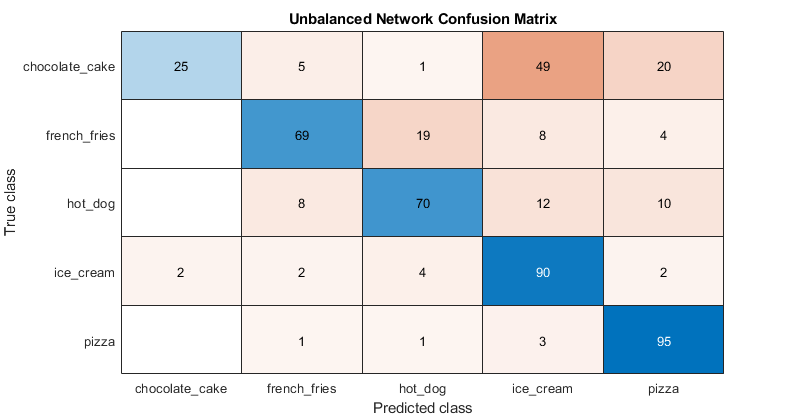

cmUnbalanced = confusionchart(testDS.Labels, labelsUnbalanced);
cmUnbalanced.Title = 'Unbalanced Network Confusion Matrix';

cmUnbalanced.RowSummary = 'row-normalized';
pause(1)

**Discussion**:

What do you notice about the total predictions made for each category (accurate or inaccurate)? Why is this the case?

- *Chocolate cake = 27*

- *French fries = 85*

- *Hot dog = 95*

- *Ice cream = 162*

- *Pizza = 131*

- *This is due to the class imbalance. Because the network learned from more images of pizza and ice cream compared to chocolate cake, it is more likely to categorize new images as one of these categories.*

Why do you think the test data was classified as ice cream more than pizza even though the class imbalance would suggest the opposite result?

- *There are many similarities between chocolate cake and ice cream compared to chocolate cake and pizza. Since this is one of the most misclassified categories, it is not surprising to see this exact mislassification often.*

## Balancing Class Weights

Based on the results in the previous section, it is clear that we need to balance the weights to obtain more accurate results. To do this, we can implement a weighted classification output layer. We do this using MATLAB's custom layer API.

The functionality of custom layers extends beyond output layers. It can be used for intermediate layers as long as you know the forward propogation and backward propogation equations for your layer.

Here, we start by calculating our class weights based on image frequency and pass these weights into our custom layer function.

classFreq = 1./[50 100 200 400 800];
classWeights = classFreq./sum(classFreq);

newLayers(end) = weightedClassificationLayer(classWeights);

weightedLayers = newLayers;

## Set Training Options

initiallearnrate = 0.001;
valDataPatience = 6;

trainOpts = trainingOptions('sgdm',...
    'InitialLearnRate',initiallearnrate,...
    'ValidationData',auValDS,...
    'Plots','training-progress',...
    'MiniBatchSize', 64,...
    'ValidationPatience', valDataPatience);

## Train Network

**Questions to consider before seeing results:**

- How do you think the overall accuracy of the network will differ compared to the unweighted network?

- Will an imbalance still be present? If so how much?

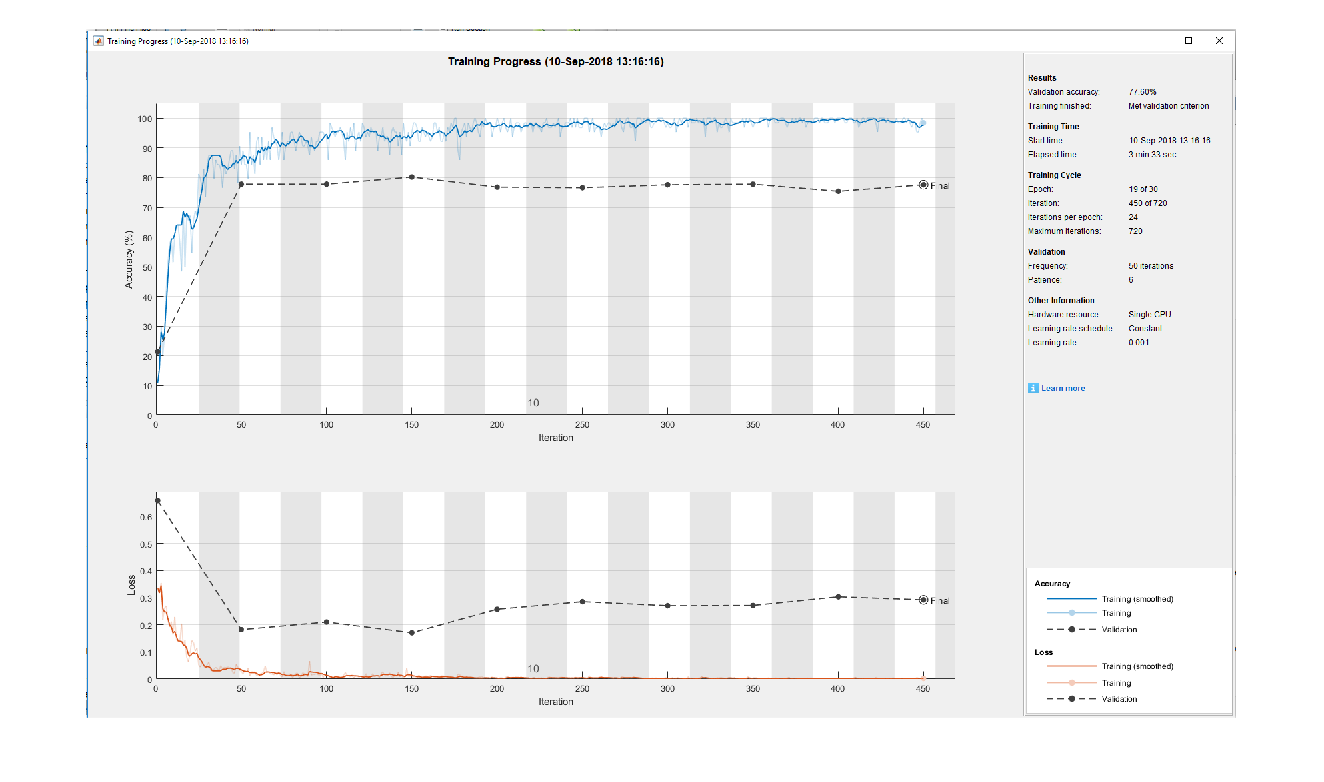

if doTrain
    netBalanced = trainNetwork(auimds, weightedLayers, trainOpts);
else
    load('netBalanced.mat');
    imshow(imread('netBalanced.PNG'));
end

## Test Network

if doTest
    [labelsBalanced scoreBalanced] = classify(netBalanced, auTestDS);
    accuracyBalanced = sum(labelsBalanced == testDS.Labels)/numel(labelsBalanced);
else
    load('netBalancedResults.mat')
end

Balanced Accuracy: 75.8%


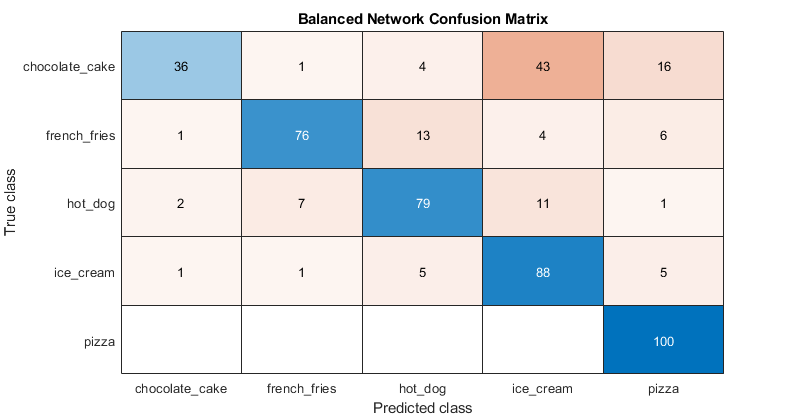

disp(['Balanced Accuracy: ' num2str(accuracyBalanced*100) '%'])
cmBalanced = confusionchart(testDS.Labels, labelsBalanced);

cmBalanced.Title = 'Balanced Network Confusion Matrix';
cmBalanced.RowSummary = 'row-normalized';
pause(1)

**Observations**:

- There is an increase across almost every category.

- French fries and chocolate cake benefitted greatly from class balancing.

- Ice cream decreased by two percent. 

**Discussion**:

Chocolate cake ihas improved, but is still quite low. What could this mean?

- *This indicates that class weighting cannot compensate for the lack of data samples - we need more than 50, especially when the other categories have up to 20 times as many samples.*

Why do you think the accuracy of ice cream has dropped by 2 percent?

- *Weighting for three of the other categories has increased. Compared to the last example, the network is less likely to classify new images as ice cream. Part of this is also variability of the network. Since we retrained out network, there are new weights and biases for our trainable layers.*

## **Accuracy Comparison**

Let's look at a side-by-side comparison of the networks with a bar chart. We'll also add in the results from net600 to see how the confusion matrix compares to a network with balanced classes. 

Note: we are not using net800, because it is an outlier.

compareNetworks(labelsUnbalanced, accuracyUnbalanced, labelsBalanced, accuracyBalanced, labels, accuracy, testDS);

**Observations**:

- Net800 has highest overall accuracy

- The unbalanced and balanced networks have higher classification rates of pizza and ice cream but much lower for chocolate cake and french fries

## Key Takeaways

- Class imbalances produce imbalances in the classification - the network can only learn from the data you provide it!

- You can use class weighting with MATLAB's custom layer API to account for some imbalancing

- Even with class balancing, additional data may be needed if a category has too little training data. 

# **High Variance and Overfitting**

## **What is Variance and Overfitting?**

In deep learning, the variance and overfitting go hand-in-hand. Variance tells us how sensitive the data is to changes between the test set and training set. For example, a high variance would indicate that the model is fit really well to our training data, but does not perform as well on our validation and test set. This would indicate that our model succeeded in learning features of the training set, but cannot generalize to "real world" data. We would say that our model has overfit to our training data.

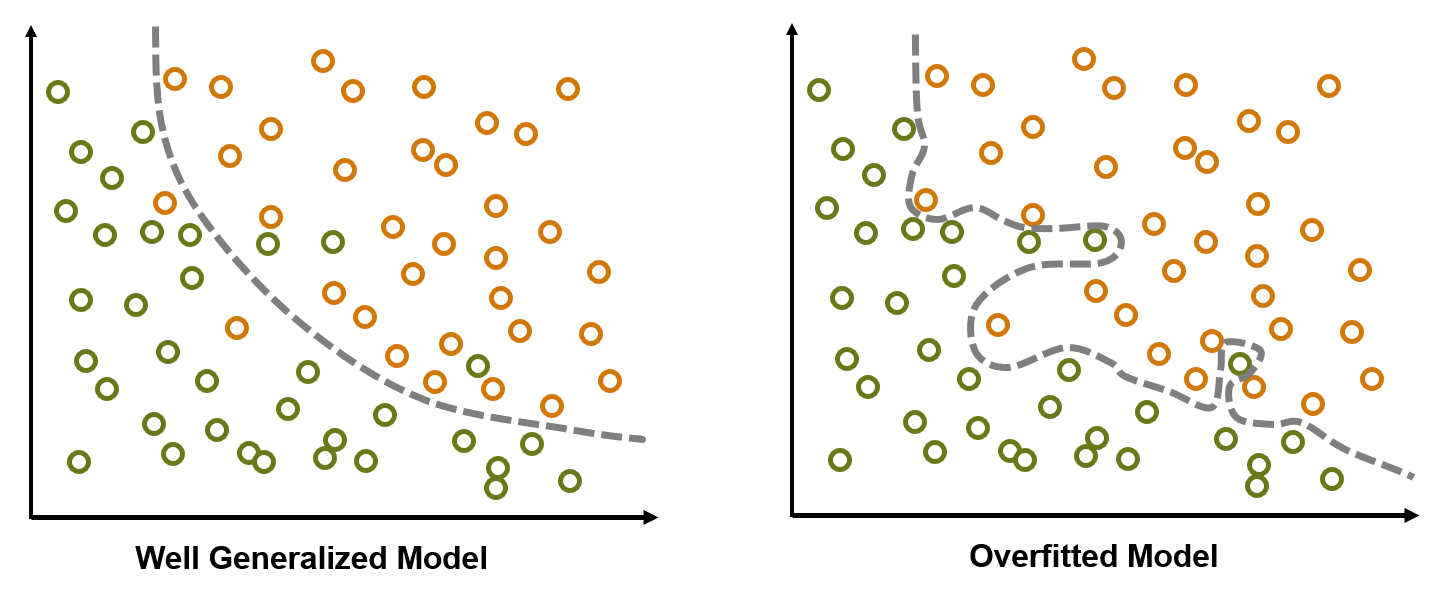

## **How is this Determined by our Training Plots?**

In our training plots, the primary indicator of high variance and possible overfitting is when we have a very high training accuracy but a lower validation accuracy. We can clearly see this disparity very clearly in some of our previous networks:

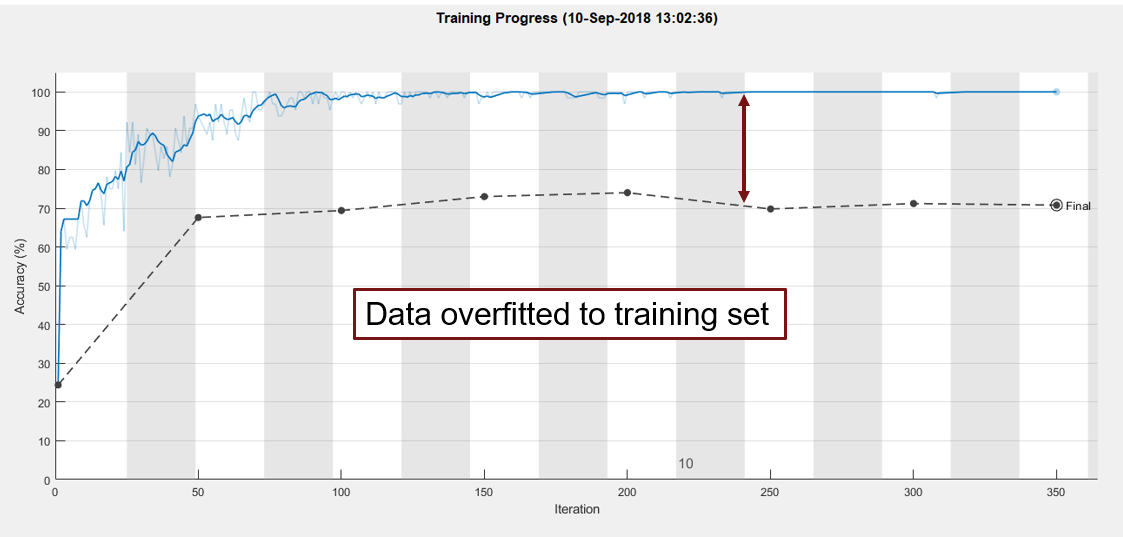

## **How to Handle Overfitting with Augmentation**

There are several techniques to handle network overfitting. Some of them include:

- More data - if you have too little training data, then it is likely that your model will fail to generalize to new data (e.g. validation and test sets)

- Dropout layers - this is a layer in the network architecture that randomly drops certain outputs as information is passed through the network. This increases the simplicity of the network, because there are less neurons that can influece the state of the final model (less complexity = less chance of overfitting). Our current network architecture has some dropout layers.

- L2 Regularization - This is a constant that is added to the loss function. It can be specified as a paramter in MATLAB. For more information on this, visit the [trainingOptions documentation](https://www.mathworks.com/help/nnet/ref/trainingoptions.html).

- **Data Augmentation - **transforming our data with random reflections, translations, and scaling increases the variability of our training set. By adding random variability to our dataset, we can improve our ability to generalize to new data (i.e. validation and test sets)

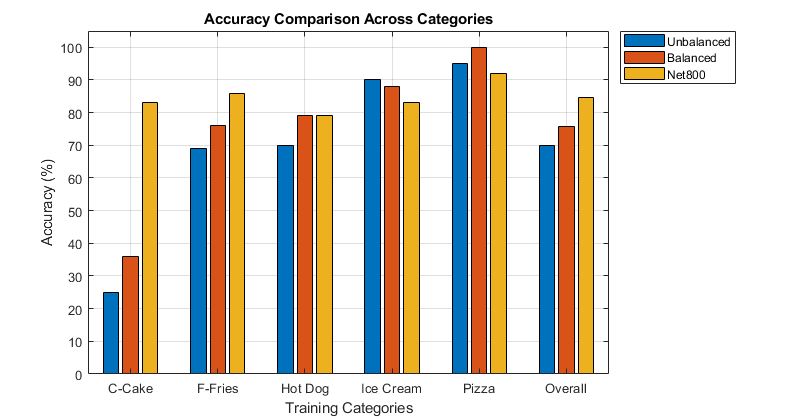

trainOpts = trainingOptions('sgdm',...

    'InitialLearnRate',0.001,...
    'ValidationData',auValDS,...
    'Plots','training-progress',...
    'MiniBatchSize', 64,...
    'ValidationPatience', 6,...
    'Shuffle','every-epoch');


Here, we will use the augmenter to transform our data. We will apply random reflections, translations, and scaling.

augmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXScale',[1 1.3], ...
    'RandYReflection',true, ...
    'RandYScale',[1 1.3], ...
    'RandXTranslation', [-40 40], ...
    'RandYTranslation', [-30 30]);

transformedImds = augmentedImageDatastore(inputSize, DS.train800,...
    'DataAugmentation',augmenter,...
    'ColorPreprocessing','gray2rgb');

if doTrain
    netTransformed = trainNetwork(transformedImds, newLayers, trainOpts);
else
    imshow(imread('netTransformed.PNG'))
end

## Test Network Accuracy

Here, we will evaluate our new model on the test dataset.

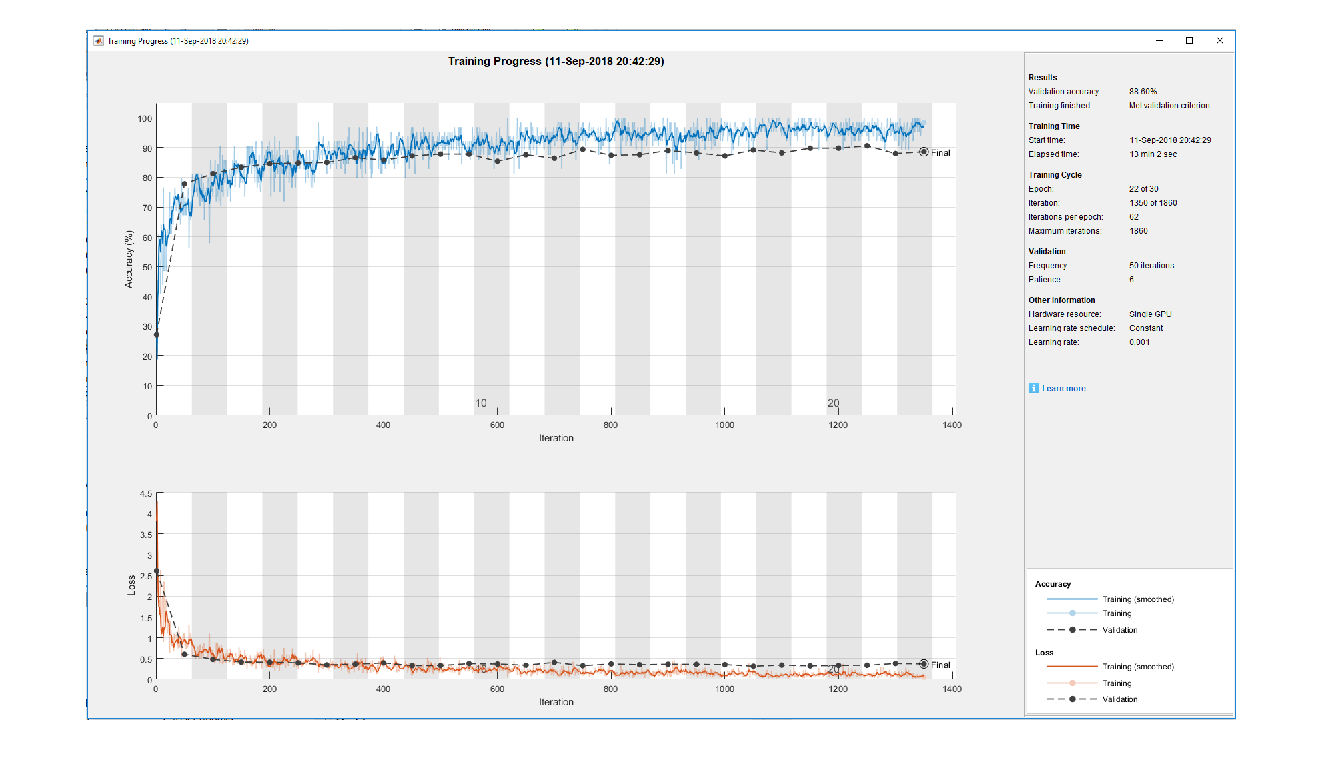

if doTest
    labelsTransformed = classify(netTransformed, auTestDS);
    accuracyTransformed = sum(labelsTransformed == testDS.Labels)/(numel(labelsTransformed));
end

## Comparing net800 with netTransformed

Below are the training images for net800 and netTransformed. 

- Blue Line = Training Accuracy

- Black Line = Validation Accuracy

- Text Box = Test Accuracy

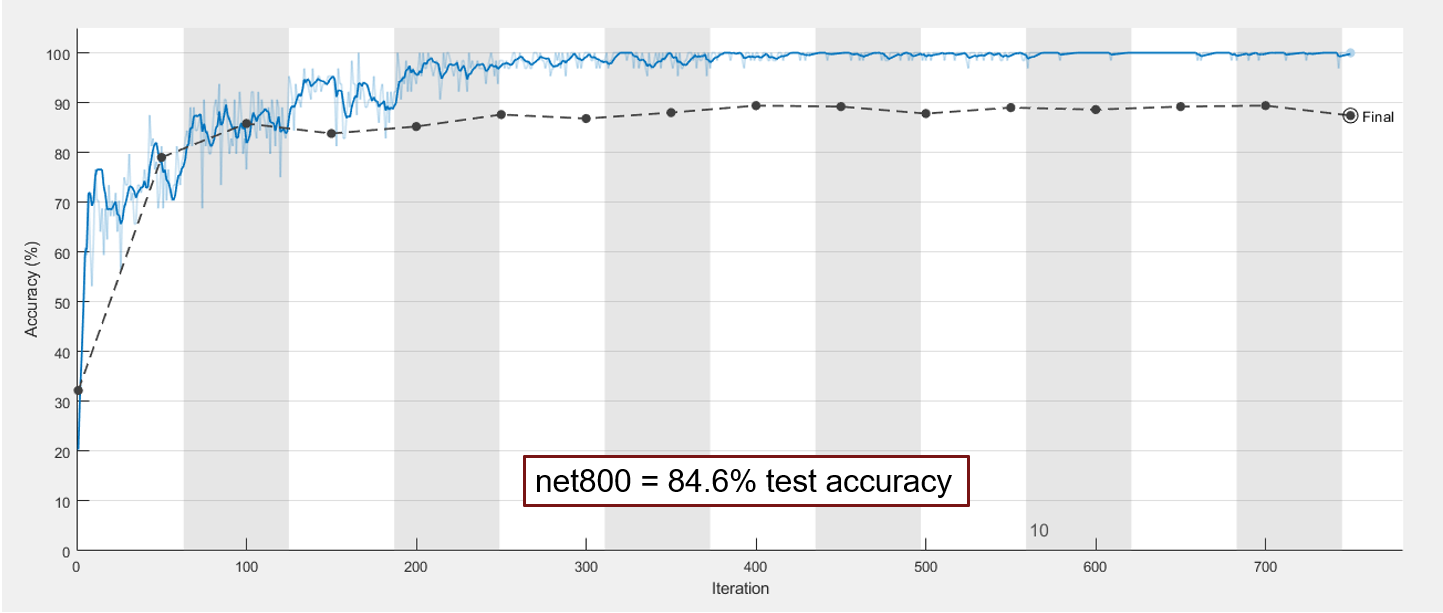 

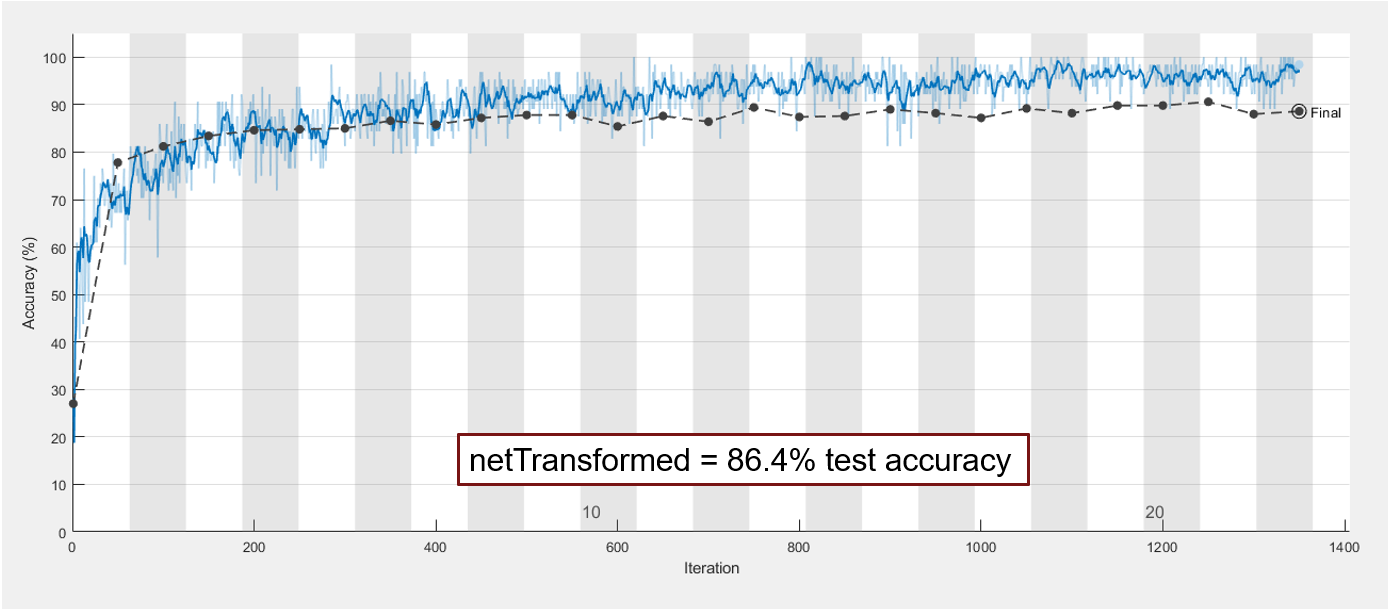

**Observations**

- netTransformed did not reach 100% training accuracy. The training accuracy and validation accuracy are very close. This means there is a low variance. It is unlikely that there is any significant overfitting in this network. This network has generalized quite well.

- net800 has a higher variance. The training accuracy reached 100%, and the network likely has some level of overfitting.

- Applying random transformations to our data improved our variance and also our test accuracy. 

## **Key Takeaways**

- Overfitting is when your network fails to generalize to your test dataset

- This is characterized by high training accuracy but a lower validation or test accuracy.

- Data augmentation is one of many techniques that can avoid overfitting and also improve the accuracy of your network.

## Other Ways to Improve Accuracy

Other Ways to Improve Accuracy

In this demo, we covered three main topics:

- Relationship between number of training examples and accuracy

- Dealing with class imbalances

- Data augmentation

We find that these are the ones people are most curious about. However, there are additional options within MATLAB that you can explore. Some of them include:

- Using different solvers – for this exercise, we used the SGDM solver. MATLAB has two other solvers you can choose from – Adam and RMS Prop. These solvers will require slightly different hyperparameter tuning.  Generally, you will find that the initial learning rate needs to be at least a factor of 5 or 10 smaller than the initial learning rate for SGDM.

- Changing network architecture – we explored this in some capacity with the MNIST Example. You can change the network architecture by defining a different network architecture from scratch or by using transfer learning with different networks. For example, if you perform transfer learning with GoogleNet and tune the hyperparameters correctly, you will achieve a higher accuracy than we did in this example (try it yourself!)

- Bayesian Optimization of Hyperparameters – the trainingOptions set for each network can have an impact on network accuracy. You can use Bayesian optimization to calculate a strong set of hyperparameters. The optimization will run a series of tests across a range of hyperparameter values and determine the ones that minimize your objective function (typically the validation error).

Deep learning, while grounded in mathematics, is also an art. As you train more networks, you will build an intuition about which factors will improve network accuracy for your dataset. 